# Rolling Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

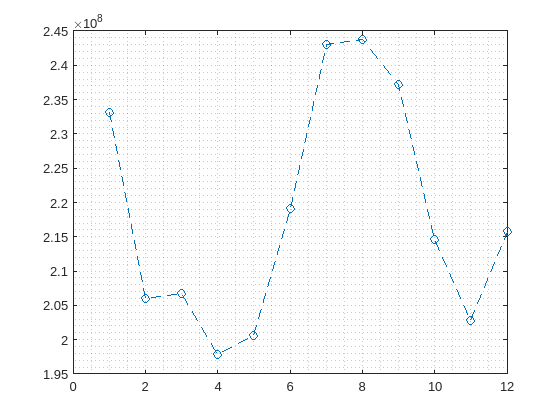

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

usage = ind + res + com;
firstYear = usage(:, 1);
plot(firstYear, "o--")
grid minor

price = price * 1000 / 100;
revenue = price .* usage;

## Task 1

diff1990 = diff(firstYear)

diff1990 =    -27089913
      706744
    -8814233
     2671160
    18604627
    23814548
      728633
    -6581330
   -22494591
   -11907913


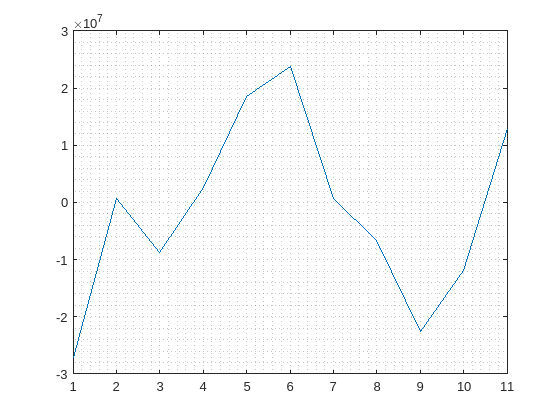

plot(diff1990)
grid minor

## Task 2

diffByMonth = diff(usage)

diffByMonth =    -27089913   -21564248   -12324251         NaN   -20738386   -15926028   -15871738   -24135542   -20913298   -32276376         NaN         NaN   -26957162   -21965520   -21416474   -29476950   -23785401         NaN   -21085653         NaN   -33391382   -37138444   -23971689   -29197488         NaN   -21910518
      706744    -5004508    -6269172         NaN    -7144499    -2692791    -6904992    -7077514     3908636     9295488         NaN    -3202402     3721237    -7793543    -8203433     7165024     8903214    -9695087         NaN    -2450300    -5917480    -4878471    -3219403     5760906    -6501504    -1758153
    -8814233    -7965580    -7898242         NaN   -11334317   -14196528         NaN    -8717569   -13830352   -13686546   -12948632   -14622963    -9547739   -17708760   -15327660         NaN   -21713019   -16222747         NaN   -18280201   -25403238   -16813152   -12964763   -19430210   -26485768   -30090419
     2671160    10197127         NaN    -120470

## Task 3

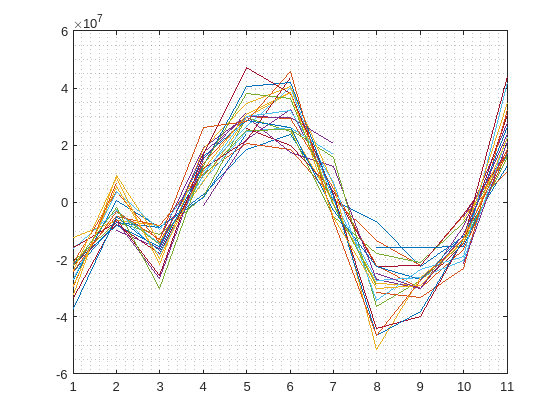

plot(diffByMonth)
grid minor

## Task 4

[maxDiffMonths,idxM] = max(diffByMonth)

maxDiffMonths =     23814548    20552790    25371177    32567112    29863339    26348047    25985009    24203462    30206807    38637143    30244449    25704818    40343247    43736208    28723791    45521636    40528884    30152758    30530220    42037612    47111597    41976937    45771030    38489857    31407359    38081986


idxM =      6     5     6     6     5     6     5     5     5     6     5     6     6     6     5     5     6     5    11    11     5     6     6     6     5     5


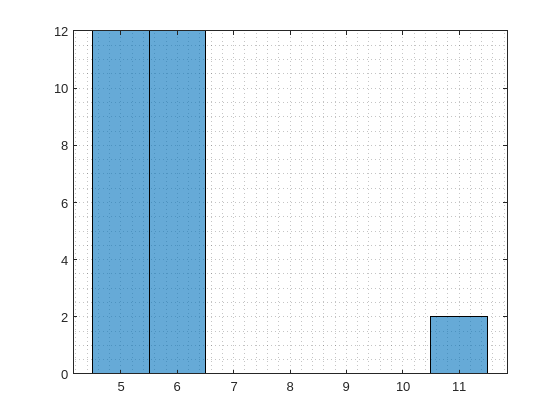

histogram(idxM)
grid minor

## Task 5

revCum = cumsum(revenue)

revCum = 1.0e+12 *

    0.1671    0.1729    0.1778    0.1821    0.1947    0.1942    0.2047    0.2098    0.2065    0.2086    0.2137       NaN    0.2279    0.2430    0.2531    0.2620    0.2904       NaN    0.3301       NaN    0.3474    0.3625    0.3540    0.3667       NaN    0.3940
    0.3212    0.3341    0.3479       NaN    0.3759    0.3796    0.3984    0.4034    0.3991    0.4011       NaN       NaN    0.4372    0.4689    0.4911    0.5056    0.5653       NaN    0.6394       NaN    0.6717    0.6901    0.6835    0.7048       NaN    0.7673
    0.4777    0.4952    0.5180       NaN    0.5568    0.5658    0.5933    0.5975    0.5956    0.6005       NaN       NaN    0.6490    0.6976    0.7302    0.7588    0.8508       NaN       NaN       NaN    0.9958    1.0259    1.0146    1.0492       NaN    1.1402
    0.6300    0.6539    0.6822       NaN    0.7331    0.7462       NaN    0.7876    0.7862    0.7934       NaN       NaN    0.8581    0.9235    0.9646       NaN    1.1269       NaN       NaN       

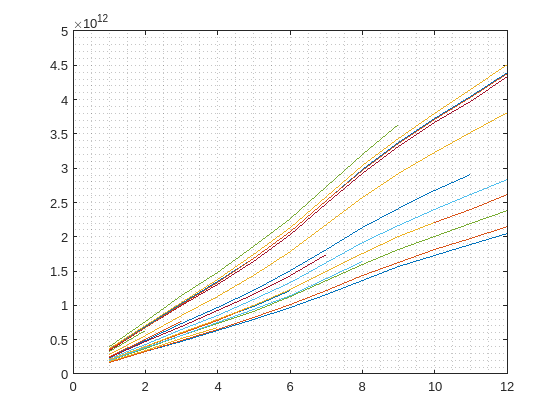

plot(revCum)
grid minor